%{
ES115 - Class-Project Module: Wind Turbine Power Output
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-27

Purpose:
    - Simulate wind turbine power output under varying wind conditions.
    - Analyze how wind variability affects instantaneous and average power.
    - Validate cubic relationship between wind speed and power.

Input:
    - User-defined blade radius
    - Time vector and wind speed models
    - Physical constants (rho, Cp)

Output:
    - Wind speed vs time plots
    - Power output vs time plots
    - Average power values
    - Console validation results
    - Exported CSV file

Engineering Algorithms:
    - Define time vector
    - Compute swept area A = pi*R^2
    - Generate wind profiles
    - Compute power using P = (1/2)*rho*A*Cp*v^3
    - Validate model using test cases
    - Apply logical checks
    - Compute averages and export results
    - Visualize results
%}

clc; clear; close all;
% clc clears command window
% clear removes all variables from workspace
% close all closes any open figure windows

%User input
R = input('Enter blade radius in meters (e.g., 40): ');
% Prompts user to input turbine blade radius


%Parameters
rho = 1.225;              
% Air density in kg/m^3 (standard atmospheric value)

Cp = 0.4;                 
% Power coefficient (efficiency of turbine)

A = pi * R^2;             
% Swept area of turbine blades (area of a circle)

t = 0:0.1:100;            
% Time vector from 0 to 100 seconds with 0.1 s increments

%Wind Speed Models

v_const = 8 * ones(size(t));       
% Creates a constant wind speed array (8 m/s for all time points)

v_step = 6 * ones(size(t));        
% Initializes wind speed at 6 m/s

v_step(t >= 50) = 12;              
% Changes wind speed to 12 m/s at time >= 50 seconds

v_sin = 8 + 2*sin(0.2*t);          
% Generates sinusoidal wind:
% Mean = 8 m/s, amplitude = 2 m/s, frequency = 0.2


%Power Calculations

P_const = windPower(rho, A, Cp, v_const);
% Computes power for constant wind using user-defined function

P_step  = windPower(rho, A, Cp, v_step);
% Computes power for step-change wind

P_sin   = windPower(rho, A, Cp, v_sin);
% Computes power for sinusoidal wind

%Function Testing

disp('--- FUNCTION TESTING ---')

--- FUNCTION TESTING ---


% Displays header in command window

v_test1 = 5;
% Test wind speed (scalar)

P_test1 = windPower(rho, A, Cp, v_test1);
% Compute power for scalar input

disp(['Test 1 - v=5 m/s → P = ', num2str(P_test1)])

Test 1 - v=5 m/s → P = 50895.7645


% Displays result of test 1

v_test2 = [4 6 8];
% Vector of wind speeds

P_test2 = windPower(rho, A, Cp, v_test2);
% Compute power for vector input

disp('Test 2 - Vector input:')

Test 2 - Vector input:


disp(v_test2)

     4     6     8



disp(P_test2)

   1.0e+05 *

    0.2606    0.8795    2.0847



% Displays vector test results

v_test3 = [4 8];
% Two wind speeds for validation

P_test3 = windPower(rho, A, Cp, v_test3);
% Compute corresponding power values

ratio = P_test3(2)/P_test3(1);
% Compute ratio to verify cubic relationship

disp(['Test 3 - Power ratio (should be ~8): ', num2str(ratio)])

Test 3 - Power ratio (should be ~8): 8


% Displays ratio (should be approximately 8)

v_test4 = 0;
% Edge case: zero wind speed

P_test4 = windPower(rho, A, Cp, v_test4);
% Power should be zero

disp(['Test 4 - v=0 → P = ', num2str(P_test4)])

Test 4 - v=0 → P = 0



v_test5 = 20;
% High wind speed test

P_test5 = windPower(rho, A, Cp, v_test5);
% Compute power at high wind

disp(['Test 5 - v=20 → P = ', num2str(P_test5)])

Test 5 - v=20 → P = 3257328.9269



%Logical Check

if max(v_sin) > 12
% Checks if sinusoidal wind exceeds 12 m/s

    disp('Warning: High wind speeds detected')
    % Displays warning message

end


%Average Power

Pavg_const = mean(P_const);
% Computes average power for constant wind

Pavg_step  = mean(P_step);
% Computes average power for step-change wind

Pavg_sin   = mean(P_sin);
% Computes average power for sinusoidal wind


%Data Exporting
output_data = [t' P_sin'];
% Combines time and sinusoidal power into matrix

writematrix(output_data, 'wind_power_output.csv');
% Exports data to CSV file

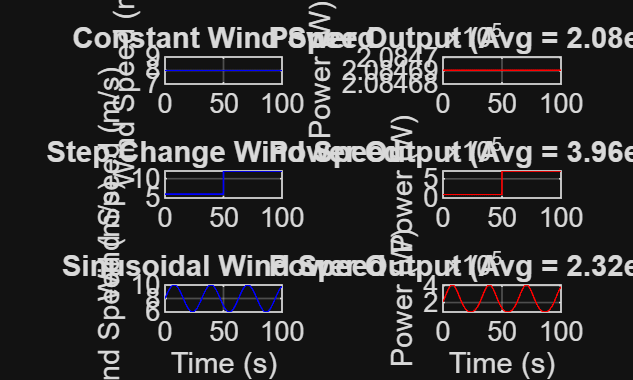


%Plots

figure;
% Opens new figure window

subplot(3,2,1)
% Creates 3x2 grid, position 1

plot(t, v_const, 'b')
% Plots constant wind speed vs time

title('Constant Wind Speed')
ylabel('Wind Speed (m/s)')
grid on

subplot(3,2,2)
plot(t, P_const, 'r')
% Plots constant power output

title(['Power Output (Avg = ', num2str(Pavg_const,'%.2e'), ' W)'])
ylabel('Power (W)')
grid on

subplot(3,2,3)
plot(t, v_step, 'b')
% Plots step wind speed

title('Step Change Wind Speed')
ylabel('Wind Speed (m/s)')
grid on

subplot(3,2,4)
plot(t, P_step, 'r')
% Plots step power output

title(['Power Output (Avg = ', num2str(Pavg_step,'%.2e'), ' W)'])
ylabel('Power (W)')
grid on

subplot(3,2,5)
plot(t, v_sin, 'b')
% Plots sinusoidal wind speed

title('Sinusoidal Wind Speed')
xlabel('Time (s)')
ylabel('Wind Speed (m/s)')
grid on

subplot(3,2,6)
plot(t, P_sin, 'r')
% Plots sinusoidal power output

title(['Power Output (Avg = ', num2str(Pavg_sin,'%.2e'), ' W)'])
xlabel('Time (s)')
ylabel('Power (W)')
grid on


%User Defined Function

function P = windPower(rho, A, Cp, v)
% Defines function to compute wind turbine power

    P = 0.5 * rho * A * Cp .* v.^3;
    % Applies wind power equation (element-wise for vectors)

end